close all; clear all;

reka = imread('reka_mala.jpg');
imwrite(reka,'reka_2.ppm');

% reka = imread('reka_zmniejszona.ppm');
%
[height, width, ch] = size(reka);

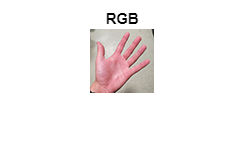

figure
imshow(reka)
title('RGB')

reka = double(reka);


R = reka(:, :, 1);
G = reka(:, :, 2);
B = reka(:, :, 3);

conv_a = [0.299 0.587 0.114; ...
    -0.168736 -0.331264 0.5; ...
    0.5 -0.418688 -0.081312];

conv_b = [0; 128; 128];

Ta=100;
Tb=145;
Tc=145;
Td=200;

for i=1:height
    for j=1:width
        R_pixel = R(i, j);
        G_pixel = G(i, j);
        B_pixel = B(i, j);
        pixel_rgb = [R_pixel; G_pixel; B_pixel];
        pixel_ycc = ( conv_a * pixel_rgb ) + conv_b; %round
        Y(i,j)=uint8(pixel_ycc(1));
        Cb(i,j) = uint8(pixel_ycc(2)); %liczba bitów musi wynosić 8!
        Cr(i,j) = uint8(pixel_ycc(3));
        pixelCb = Cb(i,j);
        pixelCr = Cr(i,j);
        if(Ta < pixelCb & pixelCb < Tb & Tc < pixelCr & pixelCr < Td)
            bin(i,j)=1;
        else
            bin(i,j)=0;
        end
    end
end

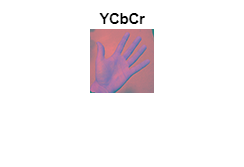

reka_ycc = cat(3, Y, Cb, Cr);
figure
imshow(reka_ycc);
title('YCbCr');

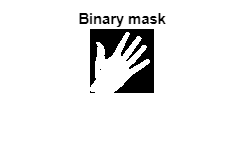

figure
imshow(bin);
title('Binary mask')

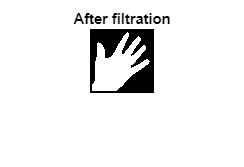

filtr = medfilt2(bin, [5,5]);
figure
filtr(1:2, :) = 0;
filtr(63:64, :) = 0;
filtr(:, 1:2) = 0;
filtr(:, 63:64) = 0;
imshow(filtr)
title('After filtration')


m00 = 0;
m10 = 0;
m01 = 0;
for i = 1:height
    for j = 1:width
        ii = i-1;
        jj = j-1;
        m00 = m00+filtr(i,j);
        m10 = m10+(ii*filtr(i,j));
        m01 = m01+(jj*filtr(i,j));
    end
end

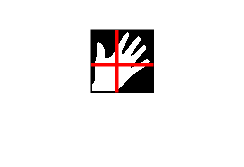

x = round(m10/m00);
y = round(m01/m00);
figure
hold on
imshow(filtr);
line([1, height], [x, x], 'color', 'r', 'LineWidth', 2);
line([y, y], [1, width], 'color', 'r', 'LineWidth', 2);


diff1=uint8(zeros(64));

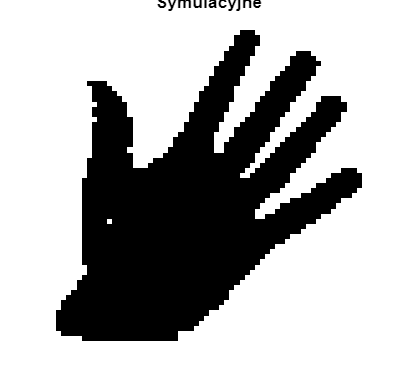

figure 
reka_bin=imread('out_bin.ppm');
bin=~bin*255;

diff =imabsdiff(reka_bin(:,:,1), uint8(bin));
imshow(reka_bin,'InitialMagnification', 1e3)
title('Symulacyjne')

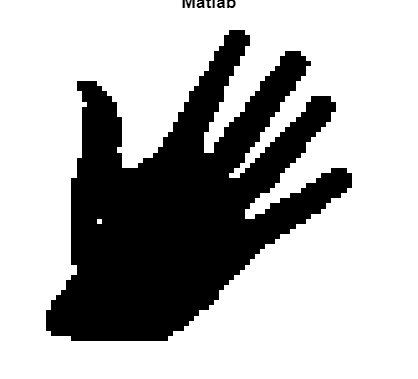


figure
imshow(bin,'InitialMagnification', 1e3)
title('Matlab')

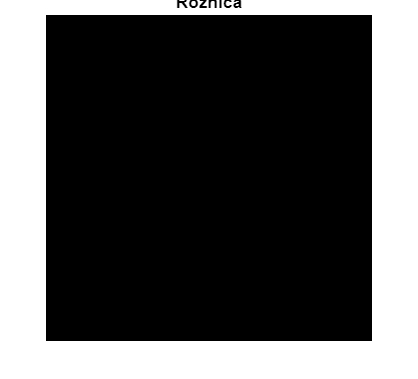


figure
imshow(diff1,'InitialMagnification', 1e3);
title('Różnica')

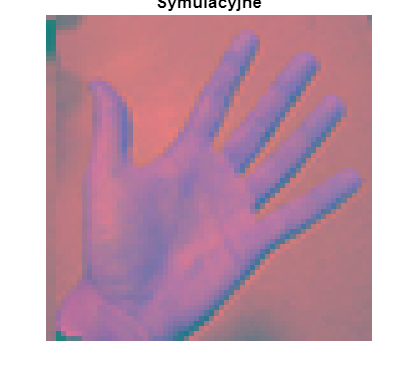



%% 

figure
reka_double_YCbCr = imread('out_ycbcr.ppm');

diff = imabsdiff(reka_double_YCbCr,  reka_ycc);

imshow(reka_double_YCbCr,'InitialMagnification', 1e3)
title('Symulacyjne')

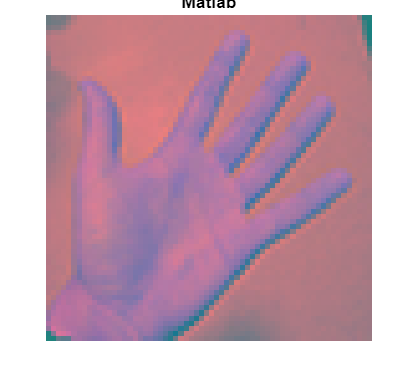


figure
imshow(reka_ycc,'InitialMagnification', 1e3)
title('Matlab')


figure
imshow(diff1,'InitialMagnification', 1e3);
title('Różnica')


max(max(diff));


%% 

function [Y,Cb,Cr] = RGB_YCbCr(RGB)

    RGB = fi(RGB,1,18,0);

    conv_1 = [0.299 0.587 0.114; ...
        -0.168736 -0.331264 0.5; ...
        0.5 -0.418688 -0.081312];
    conv_2  = [0; 128; 128];
    
    conv_1 = fi(conv_1, 1,18,17);
    conv_2 = fi(conv_2, 1, 9, 0);
    
    conv_1_RGB = fi([0 0 0; 0 0 0; 0 0 0], 1, 36, 17);
    %conv_1_RGB_quantize = fi([0 0 0; 0 0 0; 0 0 0], 1, 9, 0);

    for i = 1:3
        for j = 1:3
            conv_1_RGB(i,j) = conv_1(i, j) * RGB(j);
            %conv_1_RGB_quantize(i, j) = quantize(conv_1_RGB(i, j), 1, 9, 0); 
        end
    end
    
    
    conv_1_RGB_quantize = fi([0 0 0; 0 0 0; 0 0 0], 1, 9, 0);
    for i = 1:3
        for j = 1:3
            conv_1_RGB_quantize(i, j) = quantize(conv_1_RGB(i, j), 1, 9, 0); 
        end
    end
    
    
    conv_1_RGB_conv2 = fi([0 0 0; 0 0 0], 1, 9, 0);
    %conv_end = fi([0 0 0], 0, 8, 0);
    for i = 1:3
        conv_1_RGB_conv2(i, 1) = conv_1_RGB_quantize(i, 1) + conv_1_RGB_quantize(i, 2);
        conv_1_RGB_conv2(i, 2) = conv_1_RGB_quantize(i, 3) + conv_2(i);
        
        %conv_end(i) = conv_1_RGB_conv2(i, 1) + conv_1_RGB_conv2(i, 2);
    end
    
    conv_end = fi([0 0 0], 0, 8, 0);
    for i = 1:3
        conv_end(i) = conv_1_RGB_conv2(i, 1) + conv_1_RGB_conv2(i, 2);
    end
    
    Y =  uint8(conv_end(1));
    Cb = uint8(conv_end(2));
    Cr = uint8(conv_end(3));
end
